Combine 3D image segments into a single image

The zip file contains the original data split into 10x10 blocks of 200x200x~300. The file name gives the coordinates of each block for when you rebuild

source_dir = '~/placenta_patient_49/P49new';
placenta = [];
for j1=1:200:1801
%for j1=1:2 00:801 %half of the placenta for now
  rowSection = [];  
  for j2 = 1:200:1801
      filename = fullfile(source_dir,['stack_',num2str(j1),'_',num2str(j2),'_new.nii.gz']);
      segment = load_nii(filename);    
      rowSection = [rowSection,segment.img];
  end
  placenta=[placenta;rowSection];
end

remove voxels on the plate- these are not vessels

placenta(1:35,:,:) = 0; %(y,x,z)
placenta(1900:2000,:,:) = 0

write tiff slices from nii

tiff_dir = '~/placenta_patient_49/tiff';

dimentions =         2000        2000         268


dimentions = size(placenta);
zdim = dimentions(3);

zdim = 268

for i=1:zdim 
  slice = placenta(:,:,i:i); 
  filename = fullfile(tiff_dir,['P49_hf_slice_',num2str(i),'.tiff']);
  imwrite(uint8(slice),filename);
end

read high fidelity tiff slices (voxels on the plate have been removed)

tiff_dir = '~/placenta_patient_49/tiff';
zdim=268;
placenta = zeros(2000,2000,zdim);
for i=1:zdim
    filename = fullfile(tiff_dir,['P49_hf_slice_',num2str(i),'.tiff']);
    slice = imread(filename);
    placenta(:,:,i) = slice;
end

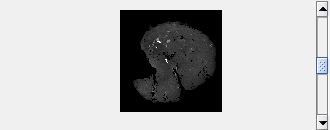

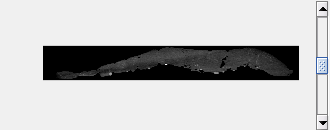

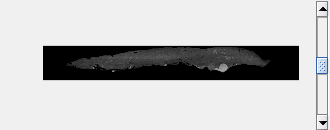

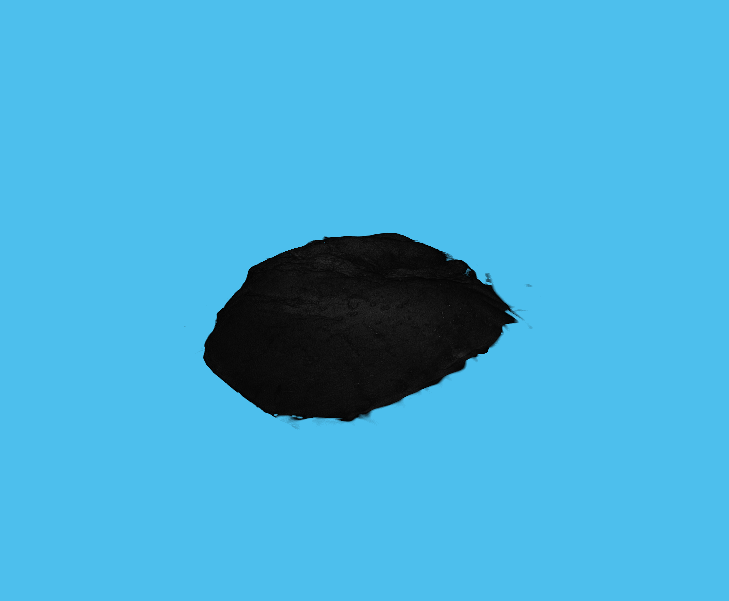

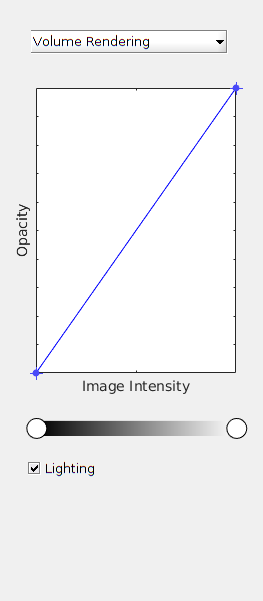

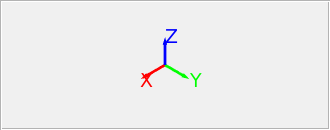

volumeViewer(placenta);

Remove non vessel placental tissue - and leave larger vessels (105)

large_vessels = placenta;
large_vessels(large_vessels < 105) = 0; %remove values less than 105 - looks like mostly chorionic vessels are kept

%vessels(vessels < 80) = 0; can see most vessels down to intermediate vessels plus maybe some placental tissue

write tiff slices of large vessels (with some large vessels)

tiff_dir = '~/placenta_patient_49/large_vessels_tiff';
dimentions = size(large_vessels);
zdim = dimentions(3);
for i=1:zdim 
  slice = large_vessels(:,:,i:i); 
  filename = fullfile(tiff_dir,['P49_lv_slice_',num2str(i),'.tiff']);
  imwrite(uint8(slice),filename);
end

Write out a point cloud text file of the large vessel surface

source_dir = '~/placenta_patient_49/isosurfaces';
lg_vessels_copy = large_vessels;
lg_vessels_copy(lg_vessels_copy >= 105)=1;
vessels_surface = isosurface(lg_vessels_copy,0);
filename = fullfile(source_dir,'large_vessel_surface.txt');
dlmwrite(filename,vessels_surface.vertices,'delimiter','\t');

Skeletonize the 3D binary volume of the large blood vessels

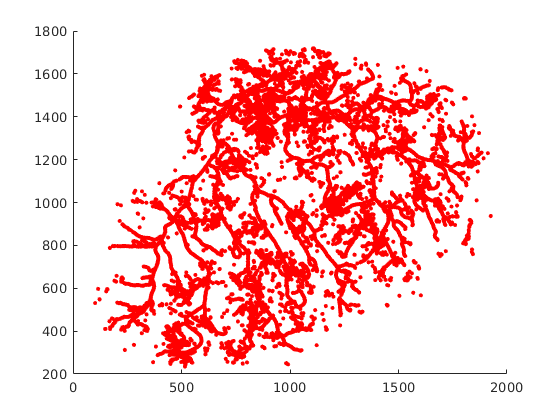

large_vessels_3D = large_vessels;
large_vessels_3D(large_vessels_3D>0) = 1;
binary_volume = logical(large_vessels_3D);
skel = Skeleton3D(binary_volume); 

clearvars -except skel;
save('skeleton');

load('skeleton');

convert a 3D binary voxel skeleton into a network graph described by nodes and edges 

A is the adjacency matrix with the length of the links as matrix entries, and node/link are the structures describing node and link properties.

A node has the following properties:

    idx List of voxel indices of this node

    links List of links connected to this node

    conn List of destinations of links of this node

    comX,comY,comZ Center of mass of all voxels of this node

    ep 1 if node is endpoint (degree 1), 0 otherwise

A link has the following properties:

    n1 Node where link starts

    n2 Node where link ends

    point List of voxel indices of this link

THR is a threshold for the minimum length of branches, to filter out skeletonization artifacts (must be set to 0 when using the modified plugin version MB_Skel2Graph3D)

THR = 0; 
[A,node,link] = MB_Skel2Graph3D(skel,THR);

Write skeleton graph to text files

Write elements

source_dir = '~/placenta_patient_49/matlab_skeleton_graph';
filename = fullfile(source_dir,'elements_large_vessels.csv');
cHeader = {'n1' 'n2' 'label'};
textHeader = strjoin(cHeader, ',');
%write header to file
fid = fopen(filename,'w'); 
fprintf(fid,'%s\n',textHeader);
fclose(fid);
%write data to end of file
elements = [link.n1;link.n2;link.label];
elements = elements';
dlmwrite(filename,elements,'delimiter',',','-append');

Write nodes

source_dir = '~/placenta_patient_49/matlab_skeleton_graph';
filename = fullfile(source_dir,'nodes_large_vessels.csv');
cHeader = {'comx' 'comy' 'comz' 'ep' 'label'};
textHeader = strjoin(cHeader, ',');
%write header to file
fid = fopen(filename,'w'); 
fprintf(fid,'%s\n',textHeader);
fclose(fid);
%write data to end of file
nodes = [node.comx;node.comy;node.comz;node.ep;node.label];
nodes = nodes';
dlmwrite(filename,nodes,'delimiter',',','-append');

zdim = 268;
placenta_volume = zeros(2000,2000,zdim);
slice = [];
for i=1:zdim
  slice = placenta(:,:,i:i); 
  slice(slice > 1) = 1; %replace all bright voxels with 1s
  %[row,col] = find(slice) %row and column subscripts of non-zero elements
  placenta_volume(:,:,i)=slice;
end

(populate placenta_volume first before running this section)

calculate placenta volume in cm3

placenta_voxels = find(placenta_volume);
no_placenta_voxels = length(placenta_voxels);
voxel_volume = 0.01165^3; % cm
placenta_volume_cm = no_placenta_voxels * voxel_volume % cm3

placenta_volume_cm = 401.7546

placenta_vascular_density = 7.1130

get vascular density for larger vessels (populate large_vessels first)

num_lg_vessel_voxels = length(find(large_vessels));
vascular_density_large_vessels = (num_lg_vessel_voxels/no_placenta_voxels)*100

vascular_density_large_vessels = 1.3589

Remove non vessel placental tissue  (80)

vessels = placenta;
vessels(vessels < 80) = 0; %can see most vessels down to intermediate vessels plus maybe some placental tissue

get vascular density for all vessels

num_vessel_voxels = length(find(vessels));
vascular_density = (num_vessel_voxels/no_placenta_voxels)*100

vascular_density = 3.3687

small_vessels = placenta;
small_vessels(small_vessels < 80) = 0;
small_vessels(small_vessels >= 105) = 0;

get vascular density for small_vessels (populate small_vessels first)

small_vessel_density = 2.0099

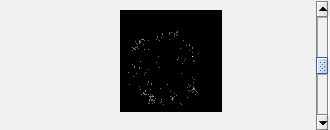

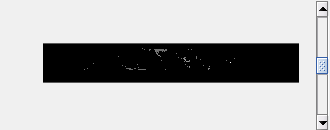

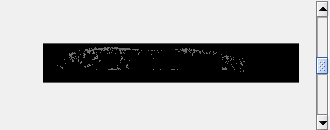

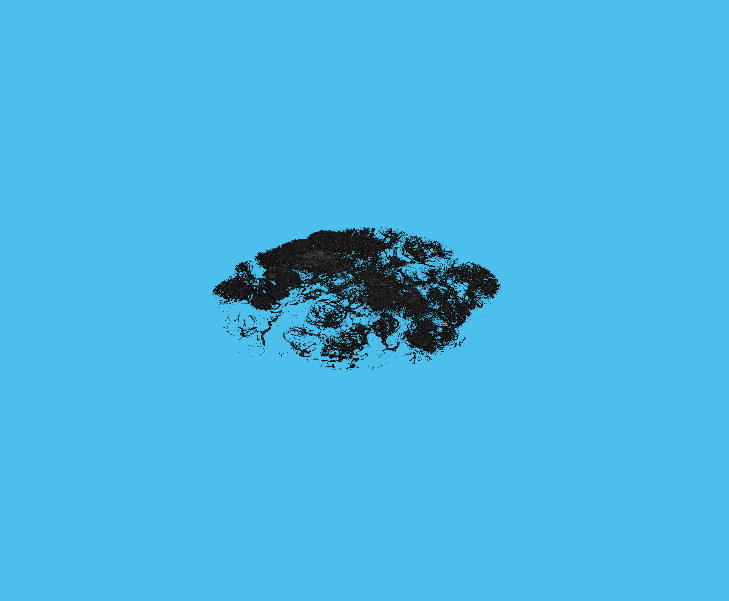

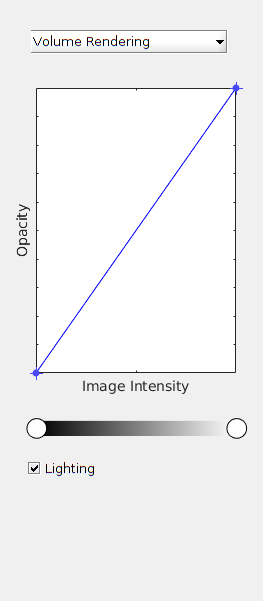

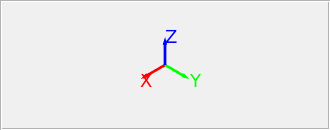

num_sm_vessel_voxels = length(find(small_vessels));
small_vessel_density = (num_sm_vessel_voxels/no_placenta_voxels)*100

write tiff slices of small vessels (with some large vessels)

tiff_dir = '~/placenta_patient_49/small_vessel_tiff';
zdim = 268;
for i=1:zdim 
  slice = small_vessels(:,:,i:i); 
  filename = fullfile(tiff_dir,['P49_sv_slice_',num2str(i),'.tiff']);
  imwrite(uint8(slice),filename);
end

read small vessel tiff slices (with some large vessels)

tiff_dir = '~/placenta_patient_49/small_vessel_tiff';
zdim = 268;
slice = [];
small_vessels = zeros(2000,2000,zdim);
for i=1:zdim
    filename = fullfile(tiff_dir,['P49_sv_slice_',num2str(i),'.tiff']);
    slice = imread(filename);
    small_vessels(:,:,i) = slice;
end

Generate seed points for growing blood vessels filling the volume of the placenta

placenta seed points every n units in each direction (populate placenta_volume first)

zdim = 268;
placenta_points = zeros(2000,2000,zdim);
num_units = 17;

for i=1:num_units:zdim
  slice = placenta_volume(:,:,i:i); 
  for j=1:num_units:2000
      for n=1:num_units:2000
          if(slice(j,n)==1)
              slice(j,n) = 2;
          end
      end
  end
  slice(slice==1) = 0;
  slice(slice==2) = 1;
  %[row,col] = find(slice) %row and column subscripts of non-zero elements
  placenta_points(:,:,i)=slice;
end

num_seeds = length(find(placenta_points))

num_seeds = 51743

Write tiff slices of placenta points - point every 5, 7, 10, 12, 15, 17, 18 or 20 units in each direction

heterogeneous distribution every 10,15 or 20 units seed_points_heterogeneous_10_15_20 (18997 points)

heterogeneous distribution every 5,10 or 15 units seed_points_heterogeneous_5_10_15 (47106 points)

heterogeneous distribution every 5,10 or 20 units seed_points_heterogeneous_5_10_20 ( 20878 points)

tiff_dir = '~/placenta_patient_49/seed_points_every_17_units';
%tiff_dir = '~/placenta_patient_49/seed_points_heterogeneous_5_10_20';
zdim = 268;
slice = [];
for i=1:zdim 
  slice = placenta_points(:,:,i:i); 
  filename = fullfile(tiff_dir,['P49_seed_points_',num2str(i),'.tiff']);
  imwrite(uint8(slice),filename);
end

write seed point coordinates to a text file

p49_seed_points_uniform_every_10_units.txt - every 10 units in the whole placenta

p49_seed_points_heterogeneous_10_15_20.txt

p49_seed_points_heterogeneous_5_10_15.txt

inds = find(placenta_points);
[y,x,z] = ind2sub(size(placenta_points),inds);
path = '~/placenta_patient_49/seed_points';
filename = fullfile(path,'p49_seed_points_heterogeneous_5_10_17.txt');
dlmwrite(filename,[x,y,z],'delimiter','\t');

Calculate placental thickness by taking slices along the x dimention every 20 voxels and recording thickness (along the z dimention) for y every 20 voxels.

Thickness is the difference between max z and min z. Average thickness is recorded. Report mean, max, min and standard deviation based on the averages.

mean_thicknesses = [];
max_thicknesses = [];
for i=1:20:2000
  vertical_slice = placenta_volume(:,i:i,:); 
  inds = find(vertical_slice);
  mean_th = 0;
  if ~isempty(inds)
     [y,z] = ind2sub(size(vertical_slice),inds);
     %get min y and max y 
     y_span = max(y) - min(y);
     %we want to take a sample every 20 voxels
     if y_span > 20
         thicknesses = [];
         for j=min(y):20:max(y)
            z_at_y = z(y==j);
            thickness_at_y = max(z_at_y) - min(z_at_y);
            thicknesses = [thicknesses,thickness_at_y]; 
            max_thicknesses = [max_thicknesses,max(thicknesses)];
         end 
         mean_th = mean(thicknesses);
      else
         %just one sample in the middle along y
         j = min(y)+floor(y_span/2);
         z_at_y = z(y==j);
         thickness_at_y = max(z_at_y) - min(z_at_y);
         mean_th = thickness_at_y;
         max_thicknesses = [max_thicknesses,mean_th];
      end
  end
  if mean_th > 0
      mean_thicknesses = [mean_thicknesses,mean_th];
  end
   
end

Maximum_thickness_value = max(max_thicknesses)*0.01165

Maximum_thickness_value = 2.4349


mean_placenta_thickness = mean(mean_thicknesses)*0.01165 %in cm

mean_placenta_thickness = 1.1423

thickness_std = std(mean_thicknesses)*0.01165

thickness_std = 0.3974

max_placenta_thickness = max(mean_thicknesses)*0.01165

max_placenta_thickness = 1.6203

min_placenta_thickness = min(mean_thicknesses)*0.01165

min_placenta_thickness = 0.1718

read tiff slices of placenta seed points (every 5 units)

zdim = 268;
tiff_dir = '~/placenta_patient_49/seed_points_every_5_units';
slice = [];
placenta_points_5 = zeros(2000,2000,zdim);
for i=1:zdim
    filename = fullfile(tiff_dir,['P49_seed_points_',num2str(i),'.tiff']);
    slice = imread(filename);
    placenta_points_5(:,:,i) = slice;
end

read tiff slices of placenta seed points (every 7 units)

zdim = 268;
tiff_dir = '~/placenta_patient_49/seed_points_every_7_units';
slice = [];
placenta_points_7 = zeros(2000,2000,zdim);
for i=1:zdim
    filename = fullfile(tiff_dir,['P49_seed_points_',num2str(i),'.tiff']);
    slice = imread(filename);
    placenta_points_7(:,:,i) = slice;
end

read tiff slices of placenta seed points (every 10 units)

zdim = 268;
tiff_dir = '~/placenta_patient_49/seed_points_every_10_units';
slice = [];
placenta_points_10 = zeros(2000,2000,zdim);
for i=1:zdim
    filename = fullfile(tiff_dir,['P49_seed_points_',num2str(i),'.tiff']);
    slice = imread(filename);
    placenta_points_10(:,:,i) = slice;
end

read tiff slices of placenta seed points (every 12 units)

zdim = 268;
tiff_dir = '~/placenta_patient_49/seed_points_every_12_units';
slice = [];
placenta_points_12 = zeros(2000,2000,zdim);
for i=1:zdim
    filename = fullfile(tiff_dir,['P49_seed_points_',num2str(i),'.tiff']);
    slice = imread(filename);
    placenta_points_12(:,:,i) = slice;
end

read tiff slices of placenta seed points (every 15 units)

zdim = 268;
tiff_dir = '~/placenta_patient_49/seed_points_every_15_units';
slice = [];
placenta_points_15 = zeros(2000,2000,zdim);
for i=1:zdim
    filename = fullfile(tiff_dir,['P49_seed_points_',num2str(i),'.tiff']);
    slice = imread(filename);
    placenta_points_15(:,:,i) = slice;
end

read tiff slices of placenta seed points (every 17 units)

zdim = 268;
tiff_dir = '~/placenta_patient_49/seed_points_every_17_units';
slice = [];
placenta_points_17 = zeros(2000,2000,zdim);
for i=1:zdim
    filename = fullfile(tiff_dir,['P49_seed_points_',num2str(i),'.tiff']);
    slice = imread(filename);
    placenta_points_17(:,:,i) = slice;
end

read tiff slices of placenta seed points (every 18 units)

zdim = 268;
tiff_dir = '~/placenta_patient_49/seed_points_every_18_units';
slice = [];
placenta_points_18 = zeros(2000,2000,zdim);
for i=1:zdim
    filename = fullfile(tiff_dir,['P49_seed_points_',num2str(i),'.tiff']);
    slice = imread(filename);
    placenta_points_18(:,:,i) = slice;
end

read tiff slices of placenta seed points (every 20 units)

zdim = 268;
tiff_dir = '~/placenta_patient_49/seed_points_every_20_units';
slice = [];
placenta_points_20 = zeros(2000,2000,zdim);
for i=1:zdim
    filename = fullfile(tiff_dir,['P49_seed_points_',num2str(i),'.tiff']);
    slice = imread(filename);
    placenta_points_20(:,:,i) = slice;
end

populate seed points depending on vascular density (fraction of vessel voxels per 24x24x24 cube)

need to do this separately for each seed density due to memory issues

load small_vessels and placenta_points17 before running this section

zdim = 268;
placenta_points = zeros(2000,2000,zdim);
cube_edge_length = 24;
vascular_density = 0;
for y=1:cube_edge_length:2000
  for x=1:cube_edge_length:2000
      for z=1:cube_edge_length:zdim
          calc_no_voxels = 0;
          y_start = y;
          y_end = y + cube_edge_length;
          if y_end > 2000
              y_end = 2000;
              calc_no_voxels = 1;
          end
          x_start = x;
          x_end = x + cube_edge_length;
          if x_end > 2000
              x_end = 2000;
              calc_no_voxels = 1;
          end
          z_start = z;
          z_end = z + cube_edge_length;
          if z_end > zdim
              z_end = zdim;
              calc_no_voxels = 1;
          end
          if calc_no_voxels
              no_of_voxels = (y_end - y_start + 1)*(x_end - x_start + 1)*(z_end - z_start + 1); 
          else
              no_of_voxels = (cube_edge_length+1)^3;
          end  
          cube = small_vessels(y_start:y_end,x_start:x_end,z_start:z_end);
          small_vessel_voxels = find(cube);
          temp_points = [];
          if ~isempty(small_vessel_voxels)
             vascular_density = length(small_vessel_voxels)/no_of_voxels; 
             if (vascular_density > 0) && (vascular_density <= 0.33)
                 placenta_points(y_start:y_end,x_start:x_end,z_start:z_end) = placenta_points_17(y_start:y_end,x_start:x_end,z_start:z_end);
             end      
          else
             %vascular density is 0
             placenta_points(y_start:y_end,x_start:x_end,z_start:z_end) = zeros(y_end - y_start + 1,x_end - x_start + 1,z_end - z_start + 1);
          end
      end
  end
end

clear placenta_points_17;
%load placenta_points_10

zdim = 268;
cube_edge_length = 24;
vascular_density = 0;
for y=1:cube_edge_length:2000
  for x=1:cube_edge_length:2000
      for z=1:cube_edge_length:zdim
          calc_no_voxels = 0;
          y_start = y;
          y_end = y + cube_edge_length;
          if y_end > 2000
              y_end = 2000;
              calc_no_voxels = 1;
          end
          x_start = x;
          x_end = x + cube_edge_length;
          if x_end > 2000
              x_end = 2000;
              calc_no_voxels = 1;
          end
          z_start = z;
          z_end = z + cube_edge_length;
          if z_end > zdim
              z_end = zdim;
              calc_no_voxels = 1;
          end
          if calc_no_voxels
              no_of_voxels = (y_end - y_start + 1)*(x_end - x_start + 1)*(z_end - z_start + 1); 
          else
              no_of_voxels = (cube_edge_length+1)^3;
          end  
          cube = small_vessels(y_start:y_end,x_start:x_end,z_start:z_end);
          small_vessel_voxels = find(cube);
          temp_points = [];
          if ~isempty(small_vessel_voxels)
             vascular_density = length(small_vessel_voxels)/no_of_voxels; 
             if (vascular_density > 0.33) && (vascular_density <= 0.66)
                 placenta_points(y_start:y_end,x_start:x_end,z_start:z_end) = placenta_points_10(y_start:y_end,x_start:x_end,z_start:z_end);
             end      
          end
      end
  end
end

clear placenta_points_10;
%load placenta_points_5

zdim = 268;
cube_edge_length = 24;
vascular_density = 0;
for y=1:cube_edge_length:2000
  for x=1:cube_edge_length:2000
      for z=1:cube_edge_length:zdim
          calc_no_voxels = 0;
          y_start = y;
          y_end = y + cube_edge_length;
          if y_end > 2000
              y_end = 2000;
              calc_no_voxels = 1;
          end
          x_start = x;
          x_end = x + cube_edge_length;
          if x_end > 2000
              x_end = 2000;
              calc_no_voxels = 1;
          end
          z_start = z;
          z_end = z + cube_edge_length;
          if z_end > zdim
              z_end = zdim;
              calc_no_voxels = 1;
          end
          if calc_no_voxels
              no_of_voxels = (y_end - y_start + 1)*(x_end - x_start + 1)*(z_end - z_start + 1); 
          else
              no_of_voxels = (cube_edge_length+1)^3;
          end  
          cube = small_vessels(y_start:y_end,x_start:x_end,z_start:z_end);
          small_vessel_voxels = find(cube);
          temp_points = [];
          if ~isempty(small_vessel_voxels)
             vascular_density = length(small_vessel_voxels)/no_of_voxels; 
             if (vascular_density > 0.66) && (vascular_density <= 1)
                 placenta_points(y_start:y_end,x_start:x_end,z_start:z_end) = placenta_points_5(y_start:y_end,x_start:x_end,z_start:z_end);
             end      
          end
      end
  end
end

clearvars -except placenta_points;
%save placenta_points to a text file

distribute vessel seed points evenly within the section of the placenta where smaller vessels are found

populate placenta_points_x and placenta (process_images.mlx)

large_vessel_inds = find(placenta == 3);
clear placenta;
placenta_points = placenta_points_23;
placenta_points(275:1500,275:1500,1:100) = 0;
placenta_points(500:1200,500:1200,1:150) = 0;
clear placenta_points_23;
placenta_points(large_vessel_inds) = 0;